% Assuming 'a' and 'b' are your target values
targetCol = [247.7395168; 53.2924886714515];


% Calculate pairwise distances between QH columns and target column
distances = pdist2(QH', targetCol')

distances =   245.6602
  242.5958
  239.2853
  234.3882
  223.2216
  213.6401
  207.9214
  201.9009
  194.3728
  186.0510


% Find the index of the nearest column for each row
[minDist, nearestColIndices] = min(distances)

minDist = 1.9190

nearestColIndices = 37

qh=transpose(QH);
qh(37,1)

ans = 245.8292


qh(37,2)

ans = 53.4752

QH(37)

ans = 128.3705

QH(2,37)

ans = 53.4752

% Create logical mask (true for elements to keep)
keepMask = true(size(QH))

keepMask = 2×331 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


keepMask(:, 37)=false

keepMask = 2×331 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   1   1   1   1   1   1   1   1   1   1   1   1   1


QH

QH =     2.2071    5.2729    8.5852   13.4835   24.6542   34.2392   39.9613   45.9869   53.5191   61.8444   71.1211   79.2084   93.3215   86.8199  101.0124  108.2274  119.9623  112.7062  128.3705  135.4972  143.9025  153.4176  163.7064  172.5886  180.6769  190.3525  197.8074  200.1863  204.1521  208.9105  214.1457  218.5870  222.8702  228.7401  235.0179  240.4704  245.8292  250.6243  255.1370  257.9573  262.9404  268.5817  274.5051  278.8305  282.5934  285.8065  288.6109  291.1186  294.1287  296.4613
   61.2173   61.2084   61.2083   61.1638   61.0924   61.0211   61.0072   61.0271   60.9870   60.9068   60.8466   60.7864   60.7262   60.7663   60.6660   60.6459   60.4621   60.5596   60.3324   60.1287   59.8982   59.7178   59.3770   58.8961   58.6155   58.0143   57.5735   57.4933   57.1727   56.8921   56.3711   56.0906   55.6898   55.0887   54.5439   54.0452   53.4752   52.8815   52.4065   52.1215   51.5278   50.8153   50.0791   49.4617   48.9507   48.5285   48.1673   47.7592   47.3427   4

filteredQH = QH(:, 1:36)

filteredQH =     2.2071    5.2729    8.5852   13.4835   24.6542   34.2392   39.9613   45.9869   53.5191   61.8444   71.1211   79.2084   93.3215   86.8199  101.0124  108.2274  119.9623  112.7062  128.3705  135.4972  143.9025  153.4176  163.7064  172.5886  180.6769  190.3525  197.8074  200.1863  204.1521  208.9105  214.1457  218.5870  222.8702  228.7401  235.0179  240.4704
   61.2173   61.2084   61.2083   61.1638   61.0924   61.0211   61.0072   61.0271   60.9870   60.9068   60.8466   60.7864   60.7262   60.7663   60.6660   60.6459   60.4621   60.5596   60.3324   60.1287   59.8982   59.7178   59.3770   58.8961   58.6155   58.0143   57.5735   57.4933   57.1727   56.8921   56.3711   56.0906   55.6898   55.0887   54.5439   54.0452


% Create logical mask (true for elements to keep, false for column 37)
keepMask = true(size(QH));
keepMask(:, 37) = false;

% Extract all elements except column 37
filteredQH = QH(keepMask)

filteredQH =     2.2071
   61.2173
    5.2729
   61.2084
    8.5852
   61.2083
   13.4835
   61.1638
   24.6542
   61.0924


% Reshape to maintain the original structure
filteredQH = reshape(filteredQH, [size(QH, 1) size(QH, 2) - 1])

filteredQH =     2.2071    5.2729    8.5852   13.4835   24.6542   34.2392   39.9613   45.9869   53.5191   61.8444   71.1211   79.2084   93.3215   86.8199  101.0124  108.2274  119.9623  112.7062  128.3705  135.4972  143.9025  153.4176  163.7064  172.5886  180.6769  190.3525  197.8074  200.1863  204.1521  208.9105  214.1457  218.5870  222.8702  228.7401  235.0179  240.4704  250.6243  255.1370  257.9573  262.9404  268.5817  274.5051  278.8305  282.5934  285.8065  288.6109  291.1186  294.1287  296.4613  299.0626
   61.2173   61.2084   61.2083   61.1638   61.0924   61.0211   61.0072   61.0271   60.9870   60.9068   60.8466   60.7864   60.7262   60.7663   60.6660   60.6459   60.4621   60.5596   60.3324   60.1287   59.8982   59.7178   59.3770   58.8961   58.6155   58.0143   57.5735   57.4933   57.1727   56.8921   56.3711   56.0906   55.6898   55.0887   54.5439   54.0452   52.8815   52.4065   52.1215   51.5278   50.8153   50.0791   49.4617   48.9507   48.5285   48.1673   47.7592   47.3427   46.


find_nearst_point_to([247.7395168, 53.2924886714515],QH)

ans =   245.8292   53.4752


points_to_delete = [bepTable.FlowRate_m3h'; bepTable.Head_m']'% Transpose to match QH structure

points_to_delete =   247.7395   53.2925
  258.4838   59.6423
  267.0793   66.2796
  272.8096   73.4623
  296.4471   79.3712



[filtered_QH, filtered_D] = drop_nearst_point_to(points_to_delete, QH, D)

filtered_QH =     2.2071    5.2729    8.5852   13.4835   24.6542   34.2392   39.9613   45.9869   53.5191   61.8444   71.1211   79.2084   93.3215   86.8199  101.0124  108.2274  119.9623  112.7062  128.3705  135.4972  143.9025  153.4176  163.7064  172.5886  180.6769  190.3525  197.8074  200.1863  204.1521  208.9105  214.1457  218.5870  222.8702  228.7401  235.0179  240.4704  250.6243  255.1370  257.9573  262.9404  268.5817  274.5051  278.8305  282.5934  285.8065  288.6109  291.1186  294.1287  296.4613  299.0626
   61.2173   61.2084   61.2083   61.1638   61.0924   61.0211   61.0072   61.0271   60.9870   60.9068   60.8466   60.7864   60.7262   60.7663   60.6660   60.6459   60.4621   60.5596   60.3324   60.1287   59.8982   59.7178   59.3770   58.8961   58.6155   58.0143   57.5735   57.4933   57.1727   56.8921   56.3711   56.0906   55.6898   55.0887   54.5439   54.0452   52.8815   52.4065   52.1215   51.5278   50.8153   50.0791   49.4617   48.9507   48.5285   48.1673   47.7592   47.3427   46

filtered_D =    220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220





drop_nearst_point_to([247.7395168, 53.2924886714515;2,61],QH)

ans =     5.2729    8.5852   13.4835   24.6542   34.2392   39.9613   45.9869   53.5191   61.8444   71.1211   79.2084   93.3215   86.8199  101.0124  108.2274  119.9623  112.7062  128.3705  135.4972  143.9025  153.4176  163.7064  172.5886  180.6769  190.3525  197.8074  200.1863  204.1521  208.9105  214.1457  218.5870  222.8702  228.7401  235.0179  240.4704  250.6243  255.1370  257.9573  262.9404  268.5817  274.5051  278.8305  282.5934  285.8065  288.6109  291.1186  294.1287  296.4613  299.0626  301.7538
   61.2084   61.2083   61.1638   61.0924   61.0211   61.0072   61.0271   60.9870   60.9068   60.8466   60.7864   60.7262   60.7663   60.6660   60.6459   60.4621   60.5596   60.3324   60.1287   59.8982   59.7178   59.3770   58.8961   58.6155   58.0143   57.5735   57.4933   57.1727   56.8921   56.3711   56.0906   55.6898   55.0887   54.5439   54.0452   52.8815   52.4065   52.1215   51.5278   50.8153   50.0791   49.4617   48.9507   48.5285   48.1673   47.7592   47.3427   46.9802   46.6630   

% function [nearst_point,nearestColIndices] = find_nearst_point_to(point,data)
% data_trans = transpose(data);
% % Calculate pairwise distances between QH columns and target column
% distances = pdist2(data_trans, point');
% % Find the index of the nearest column for each row
% [minDist, nearestColIndices] = min(distances);
% nearst_point = [data_trans(nearestColIndices,1);data_trans(nearestColIndices,2)];
% end
% 
% 
% 
% function filtered_data=drop_nearst_point_to(point,data)
% [~,col_idx]=find_nearst_point_to(point,data);
% % Create logical mask (true for elements to keep, false for column 37)
% keepMask = true(size(data));
% keepMask(:, col_idx) = false;
% 
% % Extract all elements except column 37
% filtered_data = data(keepMask);
% % Reshape to maintain the original structure
% filtered_data = reshape(filtered_data, [size(data, 1) size(data, 2) - 1]);
% end


size(points, 2)

ans = 1

points = [
  0.5, 0.7;  % First point (x = 0.5, y = 0.7)
  0.2, 0.8; % Second point (x = 0.2, y = 0.8)
  1.0, 0.3;  % Third point (x = 1.0, y = 0.3)
];

if size(points, 2) ~= 2
  error('Input points must be a 2D array (each row represents a point).');
end



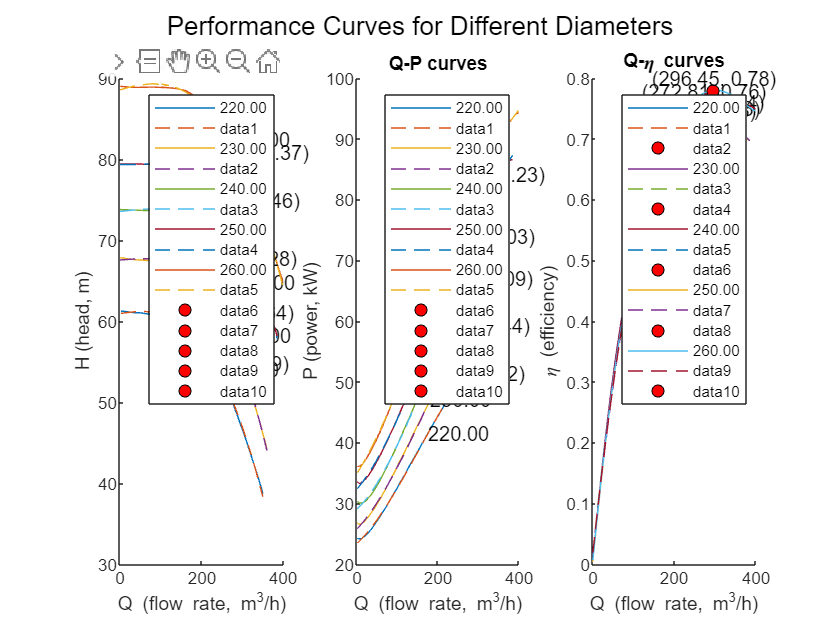

dataPath = '../../training-data';
[QH, D, QD, P] = loadData(dataPath);
fileName = 'nn_diameter-250_iteration_1_2-69-265-1-1_mseDia-2.057642e-04_test-6.064468e-03.mat';
createPerformanceCurves(QH, D, QD, P, fileName)

% function [nearest_points, nearestColIndices] = find_nearst_point_to(points, data)
% % Ensure points is a 2D array (multiple points)
% if size(points, 2) ~= 2
%   error('Input points must be a 2D array (each row represents a point).');
% end
% 
% data_trans = transpose(data);
% numPoints = size(points, 1);
% 
% % Pre-allocate for efficiency (assuming similar number of columns in points and data)
% nearest_points = zeros(numPoints, 2);
% nearestColIndices = zeros(numPoints, 1);
% 
% % Loop through each point and find nearest column
% for i = 1:numPoints
%   % Calculate pairwise distances between data columns and current point
%   distances = pdist2(data_trans, points(i,:)');
% 
%   % Find minimum distance and index
%   [minDist, nearestColIndex] = min(distances);
% 
%   % Store nearest point and index
%   nearest_points(i,:) = [data_trans(nearestColIndex,1); data_trans(nearestColIndex,2)];
%   nearestColIndices(i) = nearestColIndex;
% end
% end
% 
% function filtered_data = drop_nearst_point_to(points, data)
% % Find nearest columns for multiple points
% [nearest_points, nearestColIndices] = find_nearst_point_to(points, data);
% 
% % Get unique nearest column indices (avoiding duplicates)
% uniqueColIndices = unique(nearestColIndices);
% 
% % Create logical mask (false for columns to drop)
% keepMask = true(size(data));
% keepMask(:, uniqueColIndices) = false;
% 
% % Extract all elements except specified columns
% filtered_data = data(keepMask);
% 
% % Reshape to maintain the original structure
% filtered_data = reshape(filtered_data, [size(data, 1) size(data, 2) - numel(uniqueColIndices)]);
% end

function [nearest_points, nearestColIndices] = find_nearst_point_to(points, data)
  % Ensure points is a 2D array (multiple points)
  if size(points, 2) ~= 2
    error('Input points must be a 2D array (each row represents a point).');
  end

  data_trans = transpose(data);
  numPoints = size(points, 1);

  % Pre-allocate for efficiency
  nearest_points = zeros(numPoints, 2);
  nearestColIndices = zeros(numPoints, 1);

  % Loop through each point and find nearest column
  for i = 1:numPoints
    % Calculate pairwise distances between data columns and current point
    distances = pdist2(data_trans, points(i,:));
    
    % Find minimum distance and index
    [minDist, nearestColIndex] = min(distances);
    
    % Store nearest point and index
    nearest_points(i,:) = data_trans(nearestColIndex,:);
    nearestColIndices(i) = nearestColIndex;
  end
end

% function filtered_data = drop_nearst_point_to(points, data)
%   % Find nearest columns for multiple points
%   [nearest_points, nearestColIndices] = find_nearst_point_to(points, data);
% 
%   % Get unique nearest column indices (avoiding duplicates)
%   uniqueColIndices = unique(nearestColIndices);
% 
%   % Create logical mask (true for all columns initially)
%   keepMask = true(1, size(data, 2));
% 
%   % Set mask to false for columns to drop
%   keepMask(uniqueColIndices) = false;
% 
%   % Extract all elements except specified columns
%   filtered_data = data(:, keepMask);
% end
function [filtered_QH, filtered_D] = drop_nearst_point_to(points, QH, D)
  % Find nearest columns for multiple points
  [nearest_points, nearestColIndices] = find_nearst_point_to(points, QH);

  % Get unique nearest column indices (avoiding duplicates)
  uniqueColIndices = unique(nearestColIndices);

  % Create logical mask (true for all columns initially)
  keepMask_QH = true(1, size(QH, 2));
  keepMask_D = true(1, length(D));

  % Set mask to false for columns to drop
  keepMask_QH(uniqueColIndices) = false;
  keepMask_D(uniqueColIndices) = false;

  % Extract all elements except specified columns
  filtered_QH = QH(:, keepMask_QH);
  filtered_D = D(keepMask_D);
end

function createPerformanceCurves(QH, D, QD, P, fileName)

    % Load the .mat file
    load(fileName, 'bestTrainedNetH');

    % Constants
    rho_water = 1000;  % kg/m^3
    g = 9.81;          % m/s^2
    conversion_factor = 3600; % to convert m^3/h to m^3/s

    % Get unique diameters
    uniqueDiameters = unique(D);
    numDiameters = length(uniqueDiameters);

    % Initialize arrays to store BEP data
    bepData = [];

    polyDegree = 3;

    % Create figure with 3 subplots
    figure;

    % Subplot 1: Q-H
    subplot(1, 3, 1);
    hold on;
    qhHandles = [];
    qhPolyfits = {};
    for i = 1:numDiameters
        currentDiameter = uniqueDiameters(i);
        diameterIndices = D == currentDiameter;
        qhForDiameter = QH(:, diameterIndices);
        qhHandle = plot(qhForDiameter(1,:), qhForDiameter(2,:), 'DisplayName', sprintf('%.2f', currentDiameter));
        qhHandles = [qhHandles, qhHandle];
        % Fit polynomial to Q-H curve
        qhPolyfit = polyfit(qhForDiameter(1,:), qhForDiameter(2,:), polyDegree);
        qhPolyfits{end+1} = qhPolyfit;
        % Plot polynomial fit
        qhFit = polyval(qhPolyfit, qhForDiameter(1,:));
        plot(qhForDiameter(1,:), qhFit, '--');
        % Text label on curve (adjust position as needed)
        text(qhForDiameter(1, round(end/2)), qhForDiameter(2, round(end/2)), ...
             sprintf('%.2f', currentDiameter), 'FontSize', 10, 'VerticalAlignment', 'middle');
    end
    legend;
    xlabel('Q (flow rate, m^3/h)');
    ylabel('H (head, m)');
    title('Q-H curves');
    hold off;

    % Subplot 2: Q-P
    subplot(1, 3, 2);
    hold on;
    qpHandles = [];
    qpPolyfits = {};
    for i = 1:numDiameters
        currentDiameter = uniqueDiameters(i);
        diameterIndices = QD(2,:) == currentDiameter;
        flowRates = QD(1, diameterIndices);
        powerForDiameter = P(diameterIndices);
        qpHandle = plot(flowRates, powerForDiameter, 'DisplayName', sprintf('%.2f', currentDiameter));
        qpHandles = [qpHandles, qpHandle];
        % Fit polynomial to Q-P curve
        qpPolyfit = polyfit(flowRates, powerForDiameter, polyDegree);
        qpPolyfits{end+1} = qpPolyfit;
        % Plot polynomial fit
        qpFit = polyval(qpPolyfit, flowRates);
        plot(flowRates, qpFit, '--');
        % Text label on curve (adjust position as needed)
        text(flowRates(round(end/2)), powerForDiameter(round(end/2)), ...
             sprintf('%.2f', currentDiameter), 'FontSize', 10, 'VerticalAlignment', 'middle');
    end
    legend;
    xlabel('Q (flow rate, m^3/h)');
    ylabel('P (power, kW)');
    title('Q-P curves');
    hold off;

    % Subplot 3: Q-eta
    subplot(1, 3, 3);
    hold on;
    etaPolyfits = {};
    for i = 1:numDiameters
        currentDiameter = uniqueDiameters(i);
        diameterIndices = QD(2,:) == currentDiameter;
        flowRates = QD(1, diameterIndices);
        powerForDiameter = P(diameterIndices);

        % Convert flow rates from m^3/h to m^3/s
        flowRates_m3s = flowRates / conversion_factor;

        % Calculate predictedHead using bestTrainedNetH
        predictedHead = bestTrainedNetH([flowRates; repmat(currentDiameter, 1, length(flowRates))]);

        % Calculate efficiency
        etaForDiameter = (rho_water * g * predictedHead .* flowRates_m3s) ./ (powerForDiameter * 1000); % Convert kW to W

        % Find the best efficiency point
        [maxEta, maxIdx] = max(etaForDiameter);
        bestFlowRate = flowRates(maxIdx);
        bestEfficiency = maxEta;
        bestHead = predictedHead(maxIdx);
        bestPower = powerForDiameter(maxIdx);

        % Store BEP data
        bepData = [bepData; bestFlowRate, bestEfficiency, bestHead, bestPower, currentDiameter];

        % Plot the efficiency curve
        plot(flowRates, etaForDiameter, 'DisplayName', sprintf('%.2f', currentDiameter));
        % Fit polynomial to Q-eta curve
        etaPolyfit = polyfit(flowRates, etaForDiameter, polyDegree);
        etaPolyfits{end+1} = etaPolyfit;
        % Plot polynomial fit
        etaFit = polyval(etaPolyfit, flowRates);
        plot(flowRates, etaFit, '--');
        % Text label on curve (adjust position as needed)
        text(flowRates(round(end/2)), etaForDiameter(round(end/2)), ...
             sprintf('%.2f', currentDiameter), 'FontSize', 10, 'VerticalAlignment', 'middle');

        % Mark and label the BEP on the efficiency curve
        plot(bestFlowRate, bestEfficiency, 'ko', 'MarkerFaceColor', 'r');
        text(bestFlowRate, bestEfficiency, sprintf('(%.2f, %.2f)', bestFlowRate, bestEfficiency), ...
             'FontSize', 10, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'center');

        % Find the corresponding points on Q-H and Q-P curves and mark them
        subplot(1, 3, 1);
        hold on;
        plot(bestFlowRate, bestHead, 'ko', 'MarkerFaceColor', 'r');
        text(bestFlowRate, bestHead, sprintf('(%.2f, %.2f)', bestFlowRate, bestHead), ...
             'FontSize', 10, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'center');
        hold off;

        subplot(1, 3, 2);
        hold on;
        plot(bestFlowRate, bestPower, 'ko', 'MarkerFaceColor', 'r');
        text(bestFlowRate, bestPower, sprintf('(%.2f, %.2f)', bestFlowRate, bestPower), ...
             'FontSize', 10, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'center');
        hold off;

        % Switch back to the Q-eta subplot
        subplot(1, 3, 3);
    end
    legend;
    xlabel('Q (flow rate, m^3/h)');
    ylabel('\eta (efficiency)');
    title('Q-\eta curves');
    hold off;

    % Adjust layout and add callouts (optional)
    sgtitle('Performance Curves for Different Diameters');  % Main title

    % Save BEP data to CSV
    bepTable = array2table(bepData, 'VariableNames', {'FlowRate_m3h', 'Efficiency', 'Head_m', 'Power_kW', 'Diameter_mm'});
    writetable(bepTable, 'best_efficiency_points.csv');

    % Verify correctness of BEPs using derivatives
    syms Q;
    for i = 1:numDiameters
        currentDiameter = uniqueDiameters(i);
        % Get polynomial coefficients
        qhPolyfit = qhPolyfits{i};
        qpPolyfit = qpPolyfits{i};
        etaPolyfit = etaPolyfits{i};

        % Symbolic polynomials
        qhPoly = poly2sym(qhPolyfit, Q);
        qpPoly = poly2sym(qpPolyfit, Q);
        etaPoly = poly2sym(etaPolyfit, Q);

        % Derivatives to be continued
        detadQ = diff(etaPoly, Q);
    end
end



function [QH, D, QD, P] = loadData(dataPath)
% loadData: Loads data from files into MATLAB variables. Inputs:
%   dataPath - Path to the directory containing the data files.
% Outputs:
%   QH - Q flowrate and Head data (corresponding to D diameters).
%   (matrix) D - Diameters. (matrix) QD - Q flowrate and diameters
%   (corresponding to power in P). (matrix) P - Power values. (matrix)

% Validate data path
if ~exist(dataPath, 'dir')
    error('Data directory does not exist: %s', dataPath);
end

% Load data from files with error handling
try
    QH = load(fullfile(dataPath, 'QH.mat'));
    D = load(fullfile(dataPath, 'D.mat'));
    QD = load(fullfile(dataPath, 'QD.mat'));
    P = load(fullfile(dataPath, 'Pow.mat'));
catch ME
    error('Error loading data: %s', ME.message);
end

% Extract desired variables directly (note that this according to our own
% data only)
QH = transpose(QH.QH); %  QH struct contains a single variable named 'QH'
D = transpose(D.D);    %  D struct contains a single variable named 'D'
QD = transpose(QD.QD); %  QD struct contains a single variable named 'QD'
P = transpose(P.P);    %  P struct contains a single variable named 'P'

% the transpose here b.c the of the way train() function in matlab
% interpret the input output featrues see documentation for more info
% without transpose it would treat the whole vector or matrix as one
% input feature.
end